## Introduction

Hello and welcome to the IRACEMA User Guide.

IRACEMA is a group of MATLAB scripts made to work with Isogeometric Analysis. It was created by Guilherme Henrique da Silva and maintained by Guilherme Henrique da Silva and André Demétrio Magalhães for da Silva's Doctorate Thesis. The objective of IRACEMA is to provide an intuitive and didatic approach to learning Isogeometric Analysis.

We will provide through these Live Scripts examples and guides to how IRACEMA works. These will follow the pattern of Syntax, Description and Examples, much like Mathwork's MATLAB online help.

IRACEMA is divided in three parts: **NURBS, IGA **and **Examples**.

**NURBS **is where every algorithm of the Geometry class is included. We have most of Piegl and Tiller's The NURBS Book's Algorithms programmed in this class.

**IGA** is where the Assemblies, Shape Functions and Boundary Condition enforcement algorithms are. These are a compilation of Hughe's Isogeometric Analysis book and several papers. Here also lies da Silva's Doctorate work, mostly on Schwarz Algorithm examples.

**Examples** is self-explanatory. We hope to have working Examples of most used Differential Equations here, one day.

## The Geometry Class

The Geometry Class is the heart of IRACEMA. It is used for geometry construction, basis function evaluation, derivative evaluation, etc. The Geometry class constructor can be called in three different ways:

Naturally, these are the constructor for parametric curves of one, two and three parametric dimensions. Let's play a bit with the inputs and create a line:

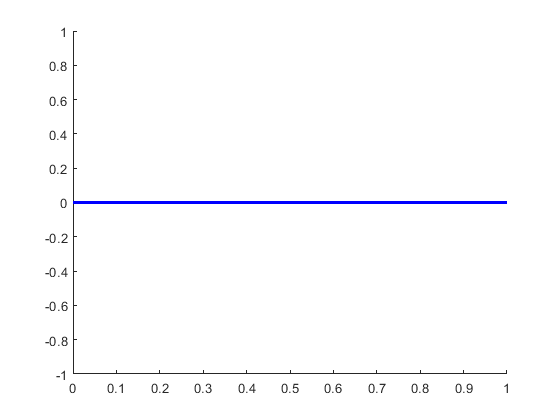

p = 1; % Polynomial Degree of the Parametric Direction
KnotVector = [0 0 1 1]; % KnotVector for a p = 1 NURBS Curve
ControlPoints = {[0 0 0 1], [1 0 0 1]};
Model = Geometry('curve',p,KnotVector,ControlPoints);
figure(1)
Model.plot_geo; % Plot the geometry

As you can see, we have constructed a Line using the Geometry Class.

Don't worry. You won't  have to manually create your models. The same can be achieved using our geometry construction algorithms, such as:

point1 = [0 0 0];
point2 = [1 0 0];
Line1 = geo_line(point1, point2); % Create a Geometry Class Object in the form of a line crossing two points.
figure(2)
Line1.plot_geo;

Which is the same line as before. We will not construct a ruled surface between two lines, using the geo_ruled function.

First, lets make another line and call it Line2:

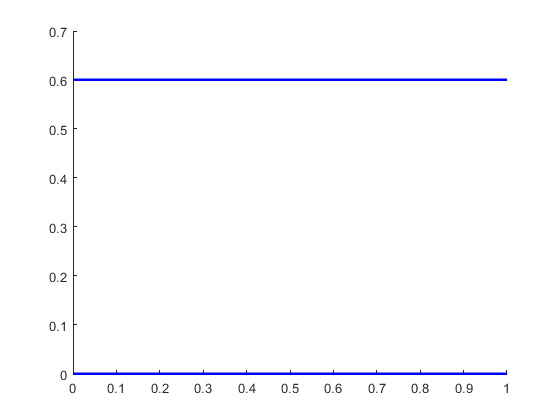

point3 = [0 0.6 0];
point4 = [1 0.6 0];
Line2 = geo_line(point3, point4);
figure(3)
Line1.plot_geo; % Our first line
hold on
Line2.plot_geo; % The line we just made

Now, to make a ruled surface:

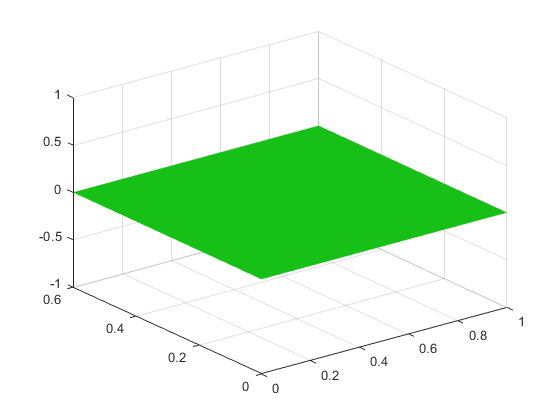

Surface = geo_ruled(Line1,Line2);
figure(4)
Surface.plot_geo;

Lets extrude this plane to make a solid, 3D plate by using geo_extrude:

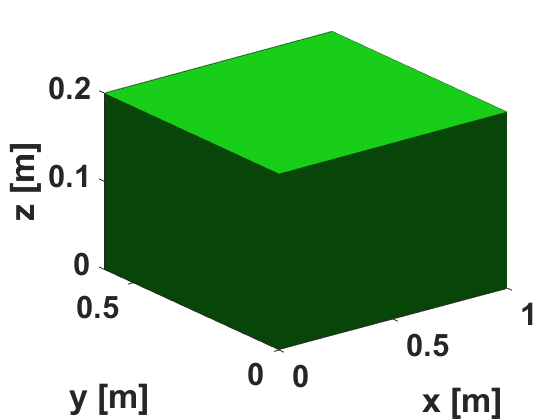

vector = [0 0 0.2]; % Direction and magnitude of extrusion
Plate = geo_extrusion(Surface,vector);
figure(5)
Plate.plot_geo;